# CoP動揺分析　複数試行・複数被験者を一度に

※　Demo03 までは理解しておくこと

copSDAP = 3.9381

copSDML = 0.9795

copSDAP = 3.0300

copSDML = 1.2098

copSDAP = 8.7813

copSDML = 5.3613

copSDAP = 7.9648

copSDML = 2.9490

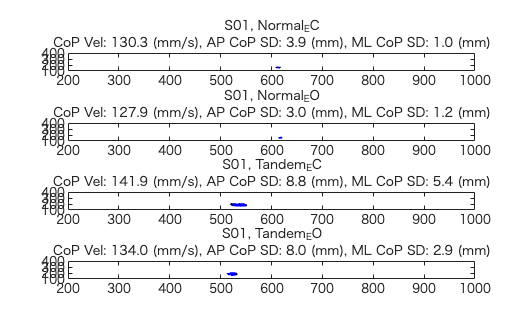

copSDAP = 10.4711

copSDML = 2.3206

copSDAP = 5.7031

copSDML = 2.1099

copSDAP = 13.2307

copSDML = 15.4848

copSDAP = 7.2864

copSDML = 17.6698

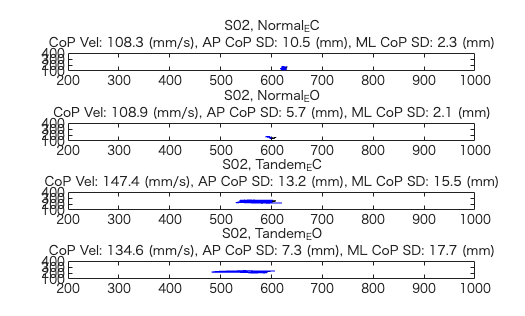

copSDAP = 3.3640

copSDML = 1.0947

copSDAP = 3.3001

copSDML = 1.0690

copSDAP = 9.5113

copSDML = 8.9958

copSDAP = 4.7993

copSDML = 4.1610

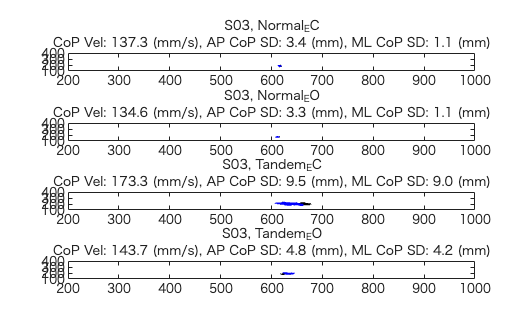

clear
close all
clc

% 分析する条件名（DataStruct内のフィールド名）
ConditionNameArray = {'Normal_EC', 'Normal_EO', 'Tandem_EC', 'Tandem_EO'} ;

% 分析区間を設定
% 静止立位のCoP動揺分析の場合、通常 20s 程度の区間を分析する
% "静止立位の定常状態"が保たれている区間を分析する必要がある
%
% 途中で姿勢が維持できなくなる等しているデータは、
% 除外するなど適切に取り扱う必要があるので細心の注意を払うこと
dur = 20000 ;
fStart = 2001 ;
fEnd = fStart + dur - 1 ; 


for iSubject = 1:3
    
    % *** 実験実習で測定計測したデータ を load***
    fileName = sprintf('StandData_S%02d', iSubject) ;
    load(fileName) ;
    
    figure(iSubject) ;
        
    
    for iCondition = 1:length(ConditionNameArray) 
        
        % cop データを抽出
        conditionName = ConditionNameArray{iCondition} ;
        cop = StandDataStruct.(conditionName).CoP ;
        copX = cop(:,1) ;
        copY = cop(:,2) ;
        
        % // CoP　指標の分析。右辺に適切な分析コードを書くこと //
        % CoP velocity: 単位時間あたりのCoP軌跡長 (mm/s)
        copDis = sum(diff(cop).^2,2).^0.5;
        copVel = sum(copDis(fStart:fEnd-1)) / (dur/1000) ;
        
        % CoP SD
        copSDAP = std(copY(fStart:fEnd))
        copSDML = std(copX(fStart:fEnd))
        
        % ////

        % 必ずプロットを確認して、異常がないか確認すること
        subplot(4,1,iCondition) ;
        plot(copX, copY, 'k') ; hold on
        plot(copX(fStart:fEnd), copY(fStart:fEnd), 'b')
        
        set(gca, 'xlim', [200,1000], 'ylim', [100, 400])
        title({[sprintf('S%02d, ', iSubject), conditionName];...
               sprintf('CoP Vel: %0.1f (mm/s), AP CoP SD: %0.1f (mm), ML CoP SD: %0.1f (mm)', copVel, copSDAP, copSDML)})
        
        % figure を保存
        filePath = sprintf('Demo12_CoPFigures/CoPFig_S%02d', iSubject) ;
        saveas(gcf, filePath, 'png')
        
        %　エキスポート用の構造体とテーブル
        S(iSubject).(['CopVel_', conditionName]) = copVel ;
        S(iSubject).(['APCoPSD_', conditionName]) = copSDAP ;
        S(iSubject).(['MLCoPSD_', conditionName]) = copSDML ;
        
    end
end

## エキスポート用の構造体とテーブル

array editor から、テーブルの数値をコピーして Excel 等に貼り付けてもよいし、writetable関数を用いて、テーブルをcsvファイルに保存してもよい。

統計検定を行う前に、プロットを確認して、分析された数値が正しいものであるか、必ず確認すること


T = struct2table(S)

T = 3×12 table
    CopVel_Normal_EC    APCoPSD_Normal_EC    MLCoPSD_Normal_EC    CopVel_Normal_EO    APCoPSD_Normal_EO    MLCoPSD_Normal_EO    CopVel_Tandem_EC    APCoPSD_Tandem_EC    MLCoPSD_Tandem_EC    CopVel_Tandem_EO    APCoPSD_Tandem_EO    MLCoPSD_Tandem_EO
    ________________    _________________    _________________    ________________    _________________    _________________    ________________    _________________    _________________    ________________    _________________    _________________

         130.29              3.9381               0.97952              127.92                3.03               1.2098               141.93              8.7813               5.3613               133.95              7.9648                2.949      
          108.3              10.471                2.3206               108.9              5.7031               2.1099                147.4              13.231               15.485               134.59              7.2864                